# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\TE-Stim_Data_nonstim_new'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 5;
Deci.Proceed            = true;  
Deci.PCom               = false;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\Radhika\TimeEst_Data\TimeEst_Processed'];    

## 1. Trial Definitions

Deci.DT.Type = 'TimeEstFun4';
Deci.DT.Starts     = {10};         %Cell Array of Markers for ETs Start.
Deci.DT.Ends       = {11};         %Cell Array of Markers for ETs End.
Deci.DT.Markers    = {[28 29 30]};

Deci.DT.Block.Start = {5};
Deci.DT.Block.Markers = {33 34};
Deci.DT.Block.End   = {6};

Deci.DT.Locks      = [12 17 27];
Deci.DT.Toi        = [-2 3]; 

## 2. PreProcessing Steps

Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.

## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];  
Deci.Art.bpf = [1 140];

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =false  ;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3]; 
Deci.Analysis.DownSample = 500;

#### Time-Frequency Analysis

Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 

Deci.Analysis.Var =false;
Deci.Analysis.Clean = true;

## 5. Plotting

    Deci.Plot.Lock = '3';
    Deci.Plot.Conditions = {[33 256] [33 261] [33 262] [33 258] [33 259] [33 264] [33 257] [33 263] [33 260] ...
                            [34 256] [34 261] [34 262] [34 258] [34 259] [34 264] [34 257] [34 263] [34 260]};
    Deci.Plot.Var = false;
    Deci.Plot.GA = true;
    Deci.Plot.Save.Format = 'pdf';

#### Math

%Deci.Plot.Math.Form = {''};   
%Deci.Plot.Math.Type = 0;


#### Conditions

Deci.Plot.Draw = {[1:3] [4:6] [7:9] [10:12] [13:15] [16:18]};
Deci.Plot.Title = {'Learned Blocks Correct Pairings' 'Learned Blocks Early Pairings' 'Learned Blocks Late Pairings' 'Unlearned Blocks Correct Pairings' 'Unlearned Blocks Early Pairings' 'Unlearned Blocks Late Pairings'};
Deci.Plot.Subtitle = {{'C-C' 'L-C' 'E-C'} {'C-E' 'L-E' 'E-E'} {'C-L' 'L-L' 'E-L'} {'C-C' 'L-C' 'E-C'} {'C-E' 'L-E' 'E-E'} {'C-L' 'L-L' 'E-L'}};
Deci.Plot.Figures = [true true true true true true false false false];

#### Time-Frequency

%Deci.Plot.Freq.Foi = [];
Deci.Plot.Freq.Foi = [4 8];
Deci.Plot.Freq.Toi = [-.5 1.5];
Deci.Plot.Freq.Channel = ['Reinhart-All'];
Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Plot.Freq.Bsl = [-.5 0];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxabs';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

Deci.Plot.Freq.Topo =1;
Deci.Plot.Freq.Square =1;

Deci.Plot.Freq.Wires.avg =  'freq';

Deci.Plot.CFC.chanlow =  {'FCz'};
Deci.Plot.CFC.chanhigh =  [{'F5' 'FCz'  'F6' }];
Deci.Plot.CFC.latencyhigh = [0 1]; %no implementation yet to check for edge artifacts so be careful
Deci.Plot.CFC.latencylow = [0 1];
Deci.Plot.CFC.freqhigh = 'beta';
Deci.Plot.CFC.freqlow = 'theta';

Deci.Plot.CFC.timebin = 5;
Deci.Plot.CFC.methods = {'mi','plv'};  % can only currently handle '' or 'mi'(pac)

Deci.Plot.CFC.Topo = 1;
Deci.Plot.CFC.Square = 1;
Deci.Plot.CFC.Hist = 1;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Total = {[1:16] [1:16]};
Deci.Plot.Behv.Acc.Subtotal = {[1:8] [9:16]};
Deci.Plot.Behv.Acc.Title = ['All Trials Percent'];
Deci.Plot.Behv.Acc.Subtitle = {'Opt Percent' 'Wst Percent'};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  true;

Deci.Plot.Behv.RT.Draw = {[1:8] [9:16]};
Deci.Plot.Behv.RT.Title = ['All Trials RT'];
Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};

Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =false;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = false;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;

## ** 6. Run**

Channel AF3 of 60
Channel AF4 of 60
Channel AF7 of 60
Channel AF8 of 60
Channel AFz of 60
Channel C1 of 60
Channel C2 of 60
Channel C3 of 60
Channel C4 of 60
Channel C5 of 60
Channel C6 of 60
Channel CP1 of 60
Channel CP2 of 60
Channel CP3 of 60
Channel CP4 of 60
Channel CP5 of 60
Channel CP6 of 60
Channel CPz of 60
Channel Cz of 60
Channel F1 of 60
Channel F2 of 60
Channel F3 of 60
Channel F4 of 60
Channel F5 of 60
Channel F6 of 60
Channel F7 of 60
Channel F8 of 60
Channel FC1 of 60
Channel FC2 of 60
Channel FC3 of 60
Channel FC4 of 60
Channel FC5 of 60
Channel FC6 of 60
Channel FCz of 60
Channel FT7 of 60
Channel FT8 of 60
Channel Fz of 60
Channel O1 of 60
Channel O2 of 60
Channel Oz of 60
Channel P1 of 60
Channel P2 of 60
Channel P3 of 60
Channel P4 of 60
Channel P5 of 60
Channel P6 of 60
Channel P7 of 60
Channel P8 of 60
Channel PO3 of 60
Channel PO4 of 60
Channel PO7 of 60
Channel PO8 of 60
Channel POz of 60
Channel Pz of 60
Channel T7 of 60
Channel T8 of 60
Channel TP10 of 60
Cha

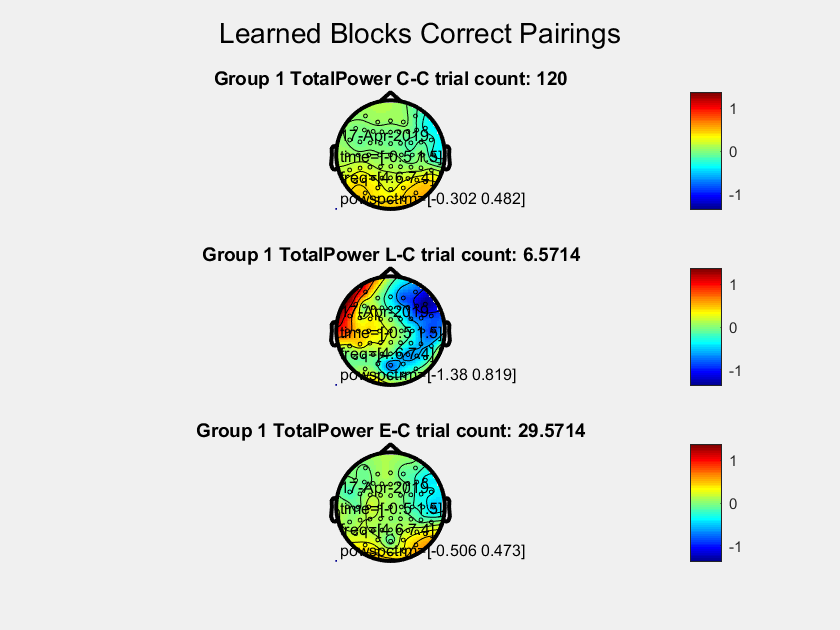

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


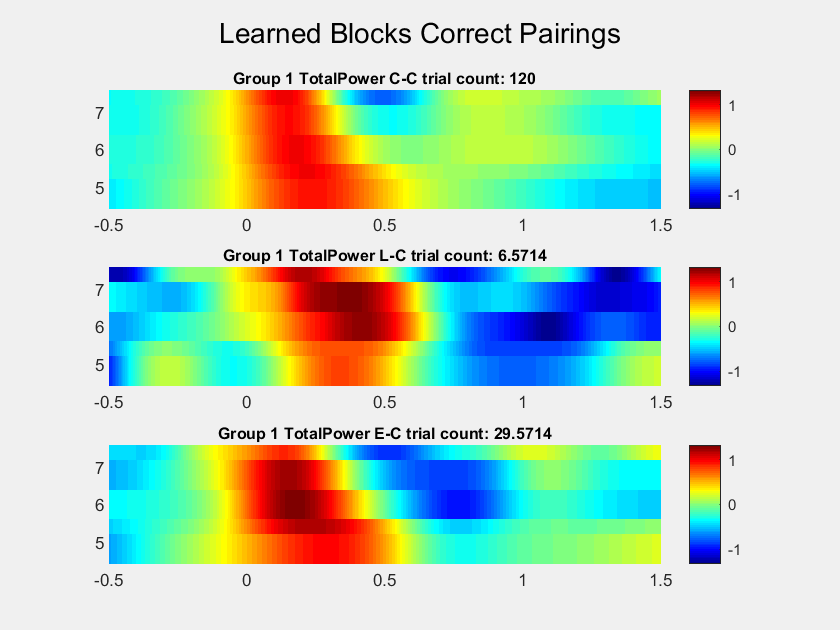

the call to "ft_singleplotTFR" took 0 seconds


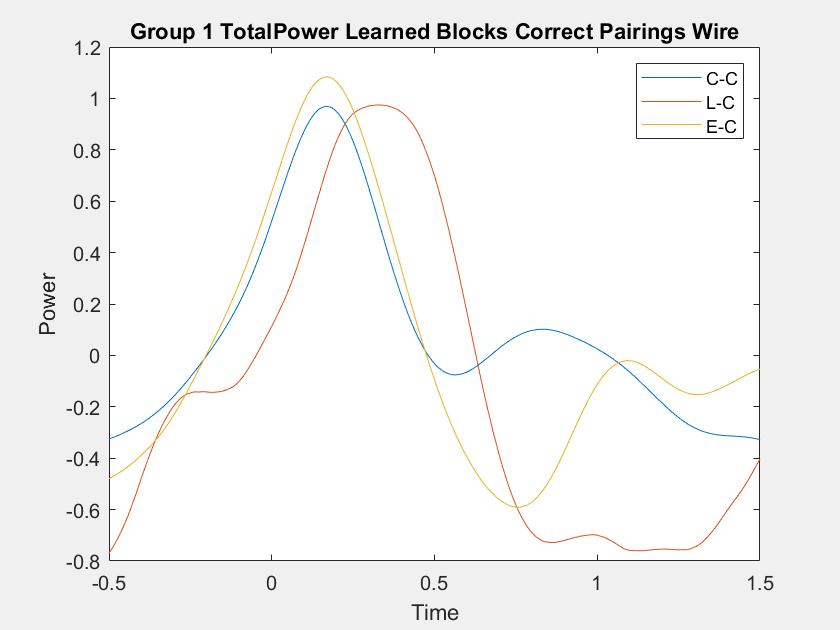

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


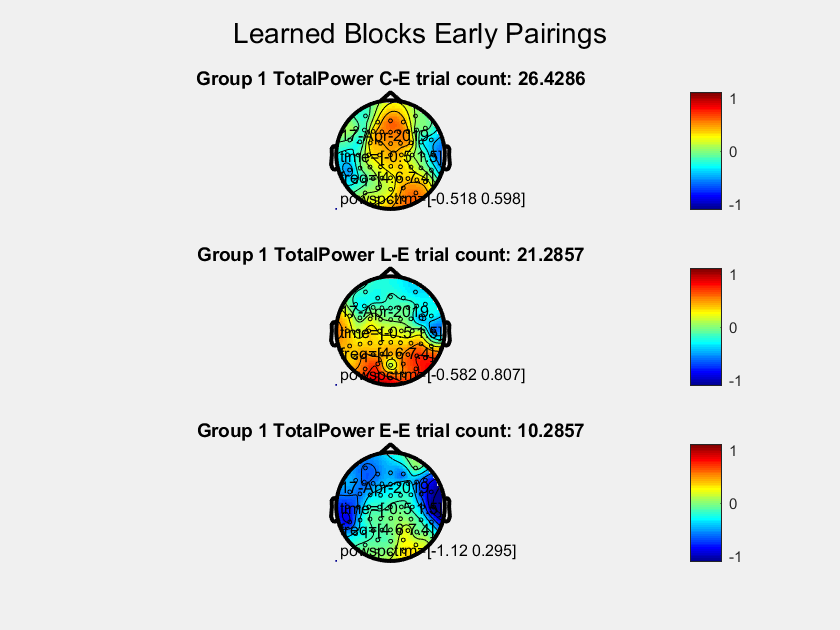

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


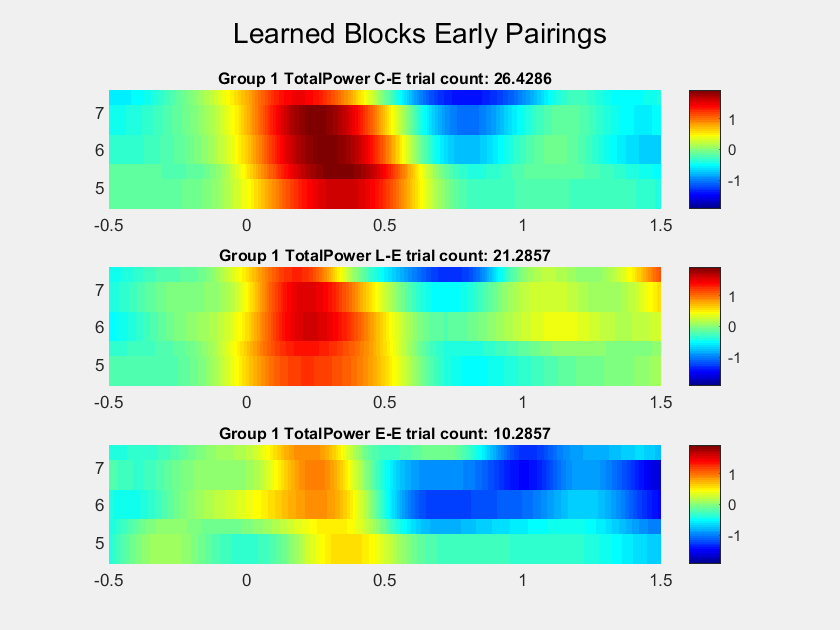

the call to "ft_singleplotTFR" took 0 seconds


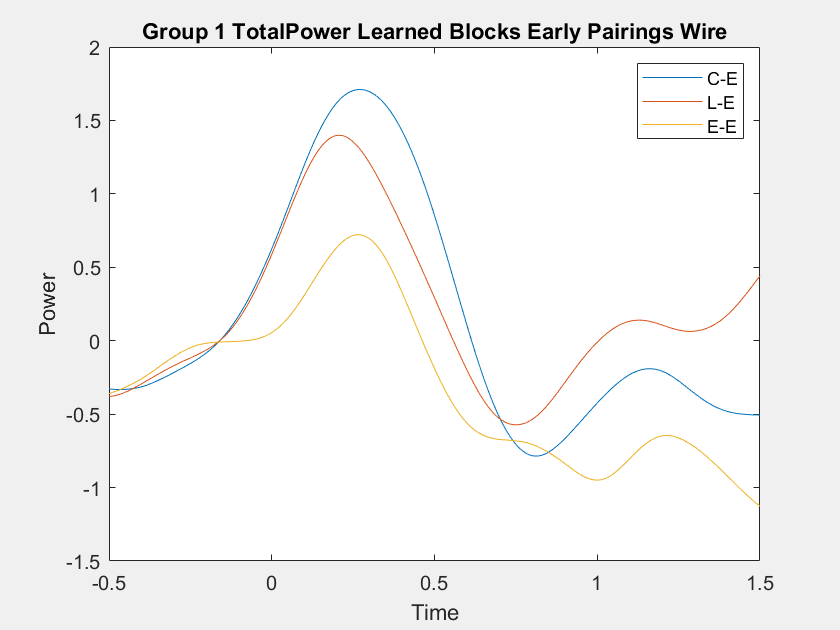

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


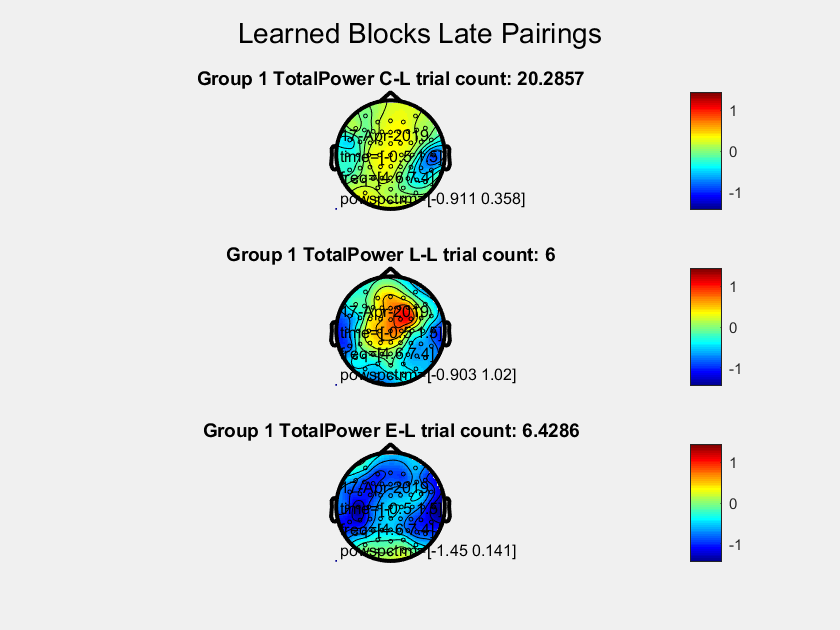

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


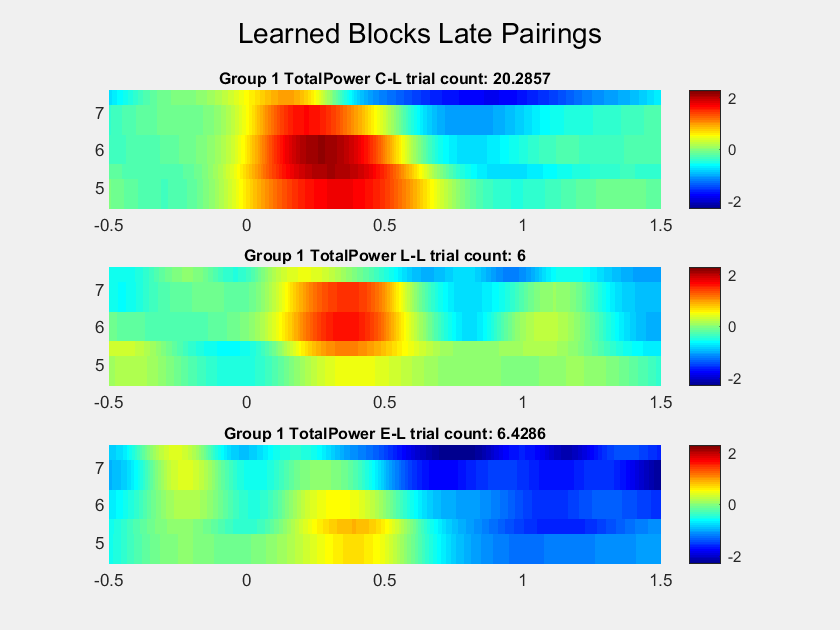

the call to "ft_singleplotTFR" took 0 seconds


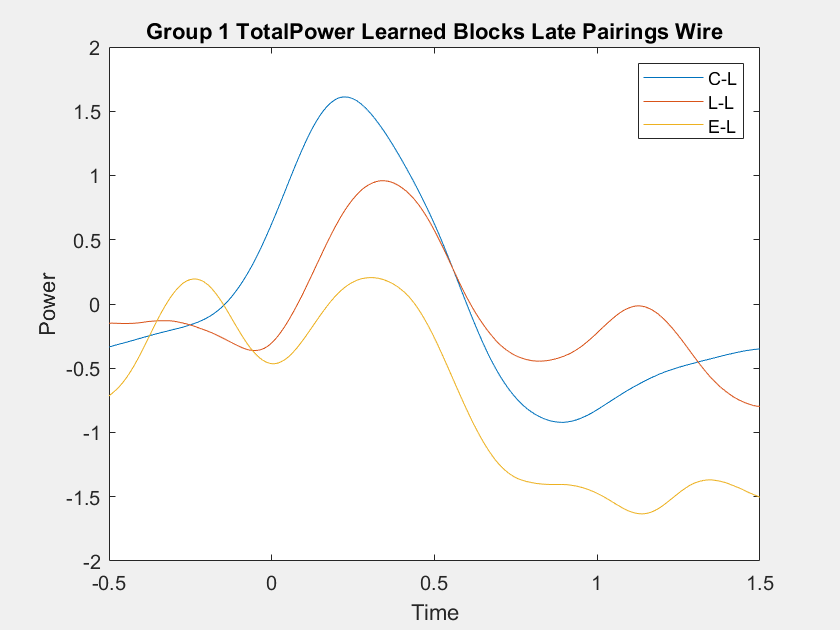

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


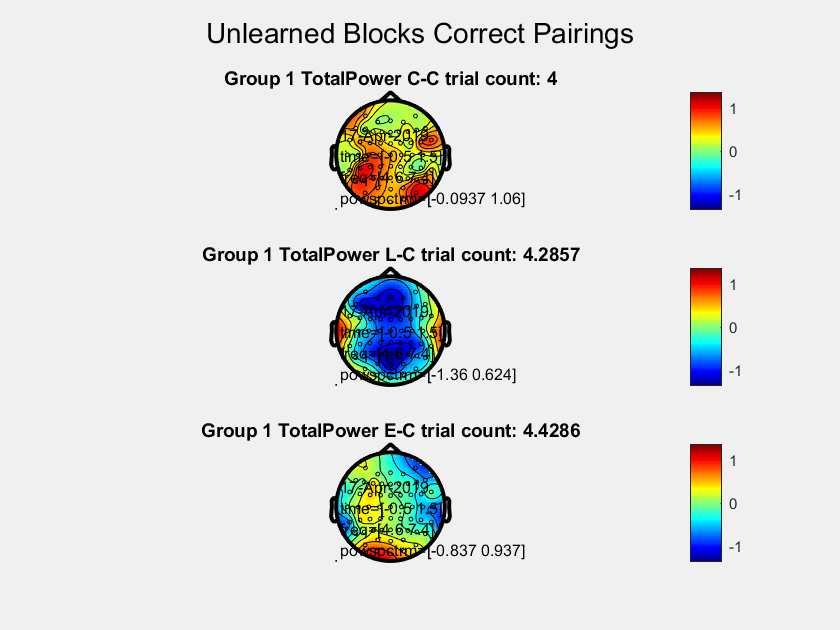

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


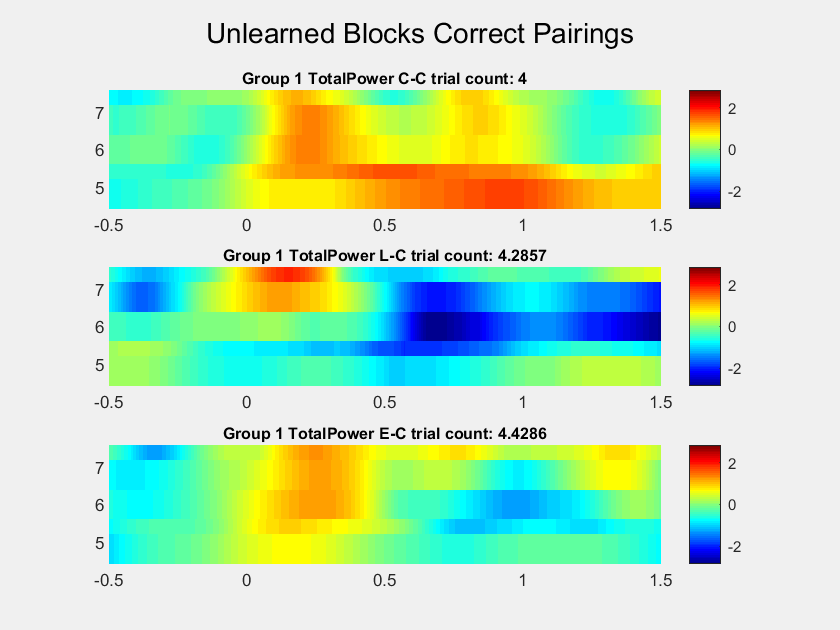

the call to "ft_singleplotTFR" took 0 seconds


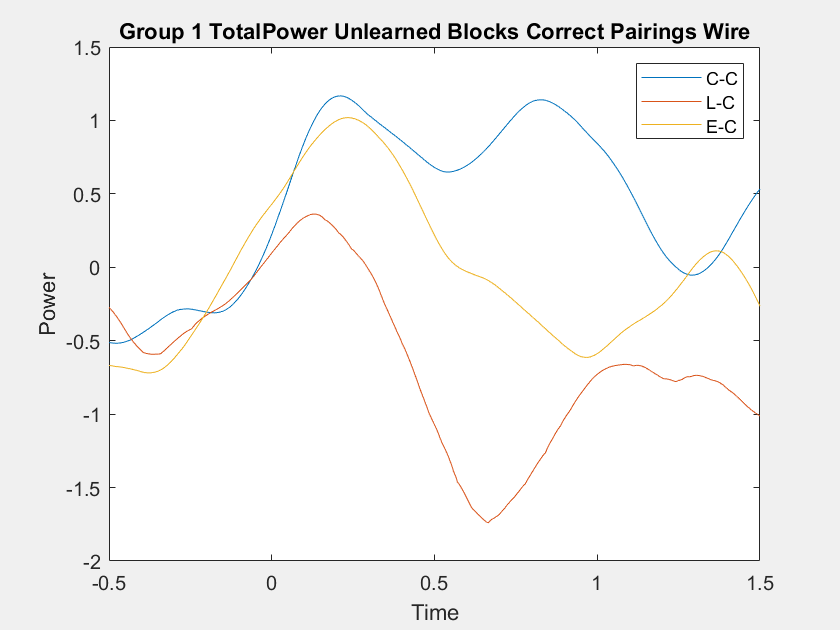

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


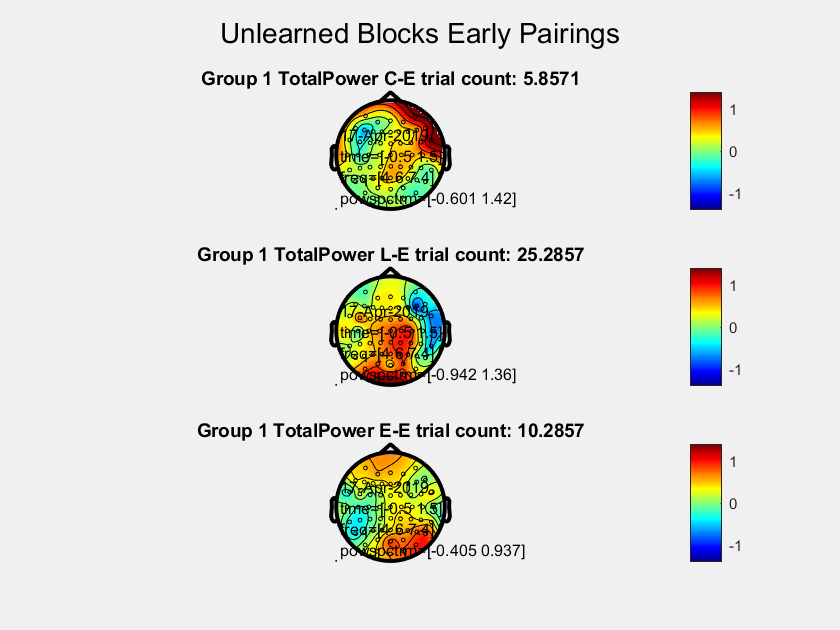

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


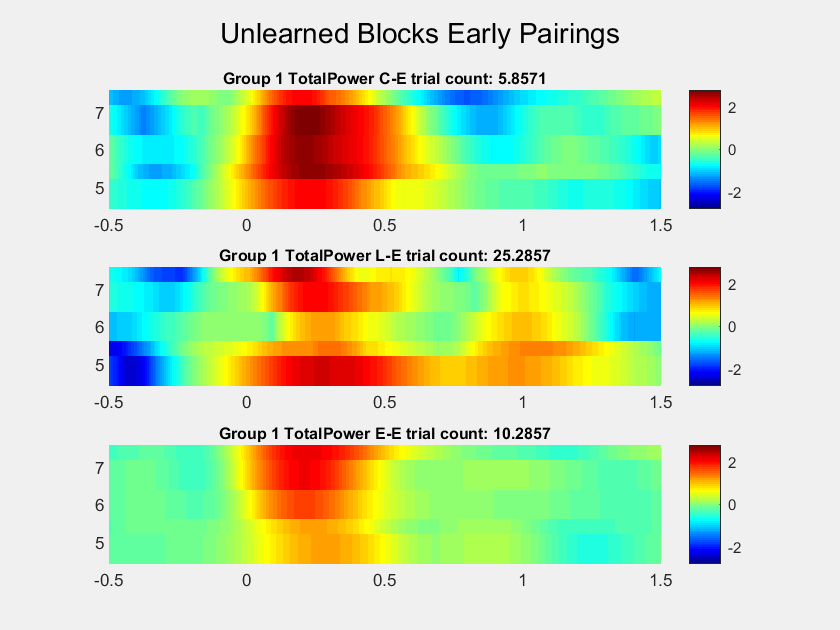

the call to "ft_singleplotTFR" took 0 seconds


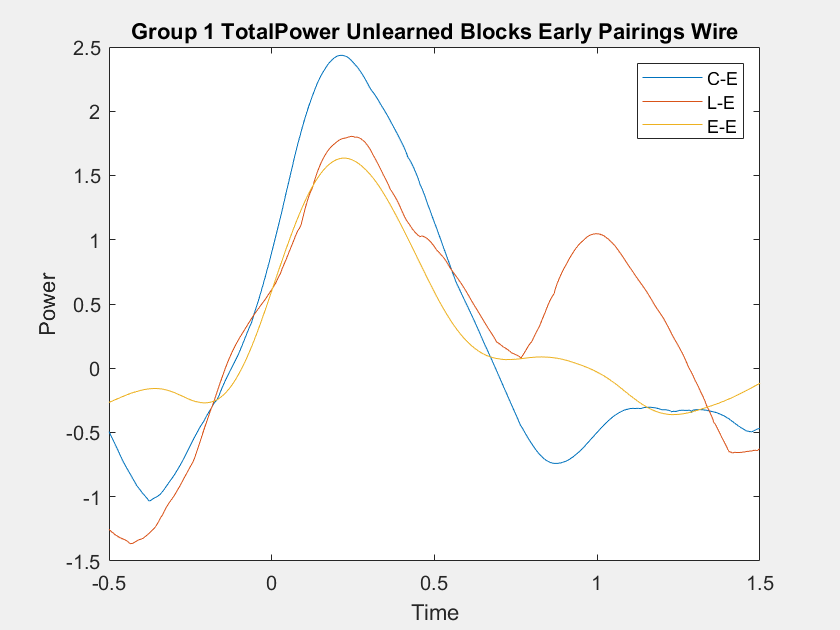

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


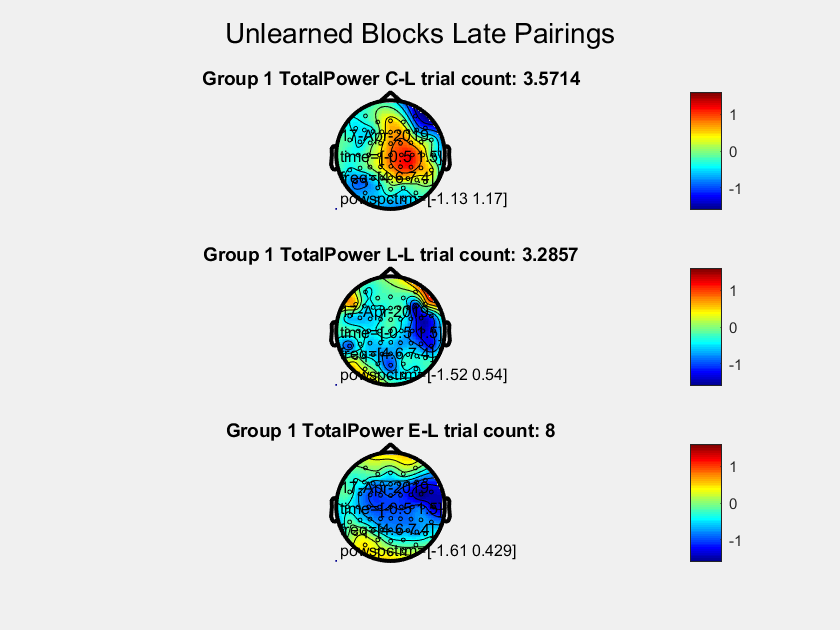

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


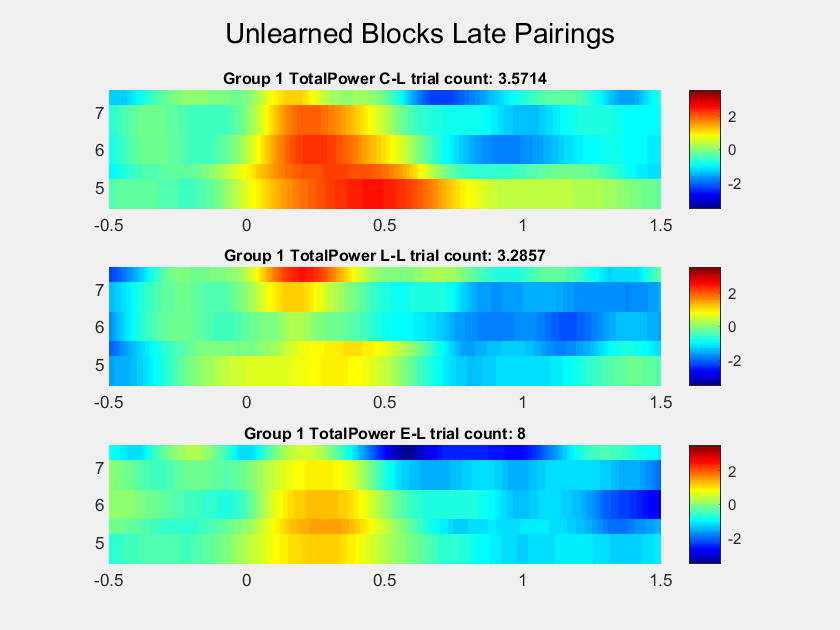

the call to "ft_singleplotTFR" took 0 seconds


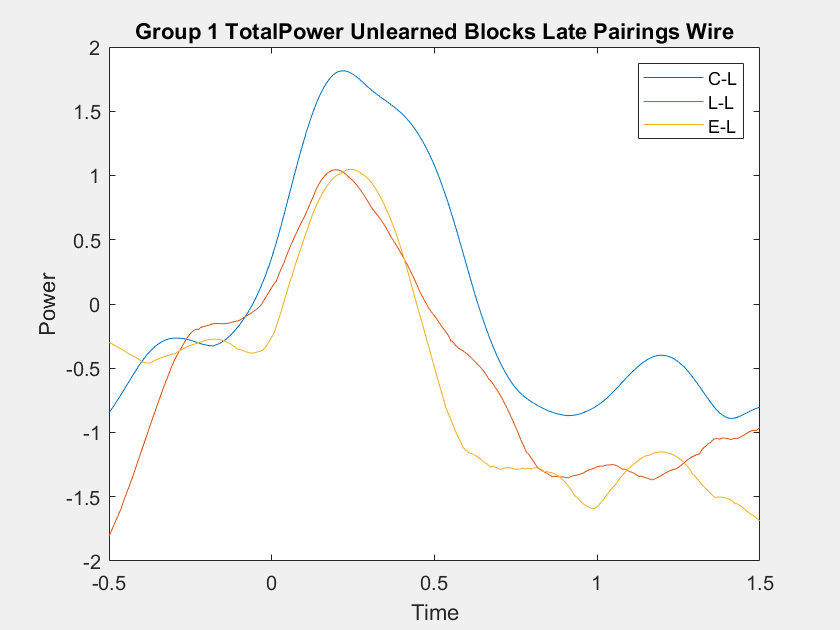

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds



Deci_Backend(Deci);